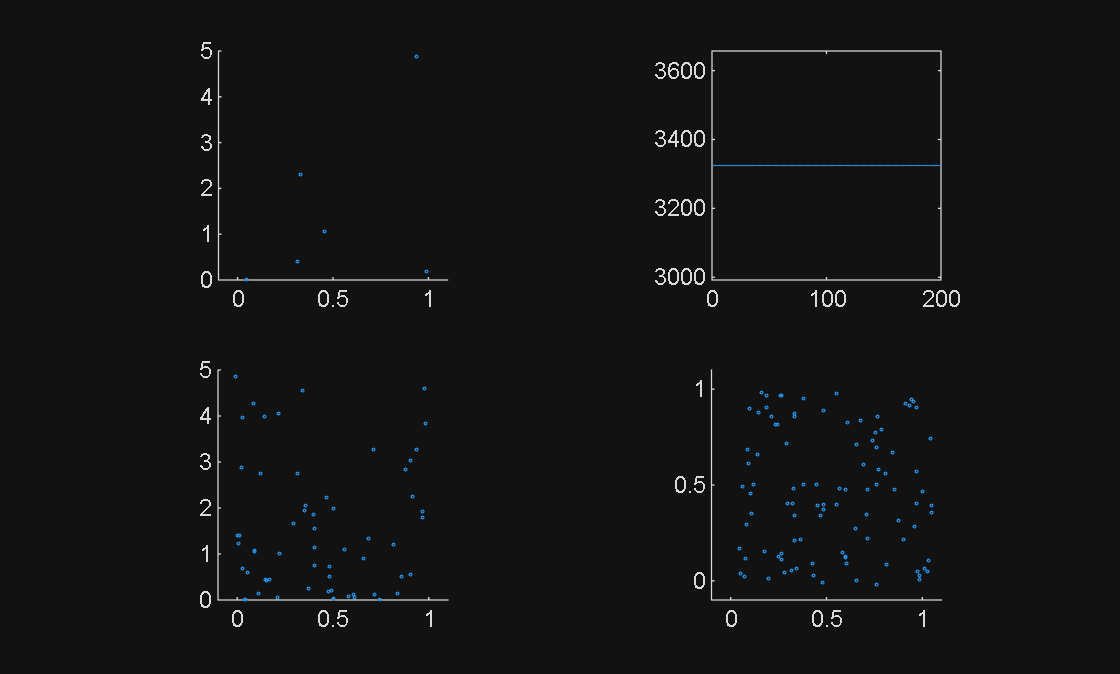

Ndim = 100;
Tdim = 200;
dt =  .01;

T = @(A) pagetranspose(A);

r = .01;
R = .25+.5*rand(Ndim,1,2);
V = 10*rand(Ndim,1,2);
V(:,:,2) = 0;
OP = ones(1,Ndim,1);

subplot(2,2,4)
S1 = scatter(R(:,1,1),R(:,1,2),1);
hold on;
% Q1 = quiver(R(:,1,1),R(:,1,2),V(:,1,1),V(:,1,2));
axis equal;
xlim([-.1 1.1])
ylim([-.1 1.1])
subplot(2,2,2)
P1 = plot([0],sum(V.^2,'all'));
xlim([0 Tdim])
ylim([.9 1.1]*sum(V.^2,'all'))
axis square;
subplot(2,2,1)
S2 = scatter(R(:,1,1),sum(V.^2,3),1);
axis square;
xlim([-.1 1.1])
ylim([0 5])
subplot(2,2,3)
S3 = scatter(R(:,1,2),sum(V.^2,3),1);
axis square;
xlim([-.1 1.1])
ylim([0 5])
drawnow;

for i=1:500

C = sparse(vecnorm((R.*OP)-T(R.*OP),2,3)-(1-eye(Ndim))*2*r<0);
PMRx = sparse(C.*((R(:,:,1).*OP)-T(R(:,:,1).*OP)));
PMRy = sparse(C.*((R(:,:,2).*OP)-T(R(:,:,2).*OP)));
PMRMs = sqrt(PMRx.^2+PMRy.^2);
PMRx = PMRx./PMRMs;
PMRy = PMRy./PMRMs;
[Xc,Yc] = find(triu(C));

% V12 = V(Xc,:)-V(Yc,:);
% nhat = [PMRx(sub2ind(size(PMRx),Xc,Yc)) PMRy(sub2ind(size(PMRy),Xc,Yc))];
% PD = sum(V12.*nhat,2).*nhat;
% V(Xc,:) = V(Xc,:) - PD;
% V(Yc,:) = V(Yc,:) + PD;
% R12 = .5*nhat.*(PMRMs(sub2ind(size(PMRMs),Xc,Yc))-2*r);
% R(Xc,:) = R(Xc,:) - R12;
% R(Yc,:) = R(Yc,:) + R12;

for Jb=1:numel(Xc)
V12 = V(Xc(Jb),:)-V(Yc(Jb),:);
nhat = [PMRx(sub2ind(size(PMRx),Xc(Jb),Yc(Jb))) PMRy(sub2ind(size(PMRy),Xc(Jb),Yc(Jb)))];
PD = sum(V12.*nhat,2).*nhat;
V(Xc(Jb),:) = V(Xc(Jb),:) - PD;
V(Yc(Jb),:) = V(Yc(Jb),:) + PD;
R12 = .5*nhat.*(PMRMs(sub2ind(size(PMRMs),Xc(Jb),Yc(Jb)))-2*r);
R(Xc(Jb),:) = R(Xc(Jb),:) - R12;
R(Yc(Jb),:) = R(Yc(Jb),:) + R12;
end



R = mod(R,1);


R = R + dt*V;

set(S1, 'XData', R(:,1,1), 'YData', R(:,1,2));
set(S2, 'XData', R(:,1,1), 'YData', sum(V(:,1,1).^2,3));
set(S3, 'XData', R(:,1,2), 'YData', sum(V(:,1,2).^2,3));
% set(Q1, 'XData', R(:,1,1), 'YData', R(:,1,2), 'UData', V(:,1,1), 'VData', V(:,1,2));
set(P1, 'YData', [get(P1,'Ydata') sum(V.^2,'all')]);
set(P1, 'XData', [get(P1,'Xdata') i]);
% set(S2,'Xdata',R(:,1,1),'Ydata',R(:,1,2),'Zdata',sum(V.^2,3))
drawnow;
end